## Polynomial interpolation - Ex. 8.1

clear all;
close all;
clc;

Approximate the function $f(x) = x sin(x)$ in the interval $[-2, 6]$

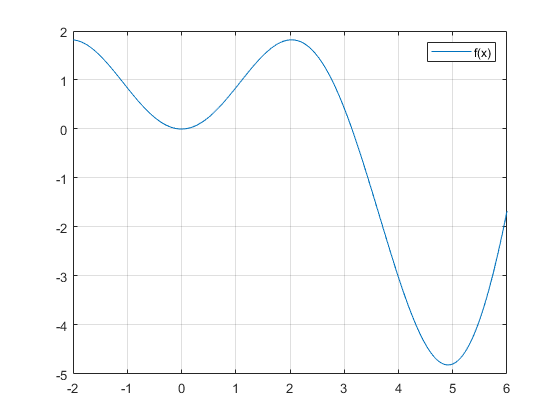

f = @(x) x.*sin(x);
a = -2;
b = 6;

x = linspace(a, b, 1000);

plot(x, f(x));
grid on;
legend('f(x)');
hold off;

### a. Consider a set of equally space nodes: find the interpolating polynomial using Lagrange basis polynomials od degree 4,6,8

d4 = 4;
d6 = 6;
d8 = 8;

x4 = linspace(a, b, d4+1);
Phi4 = polyfit(x4, f(x4), d4);
Phi4_plot = polyval(Phi4, x);

x6 = linspace(a, b, d6+1);
Phi6 = polyfit(x6, f(x6), d6);
Phi6_plot = polyval(Phi6, x);

x8 = linspace(a, b, d8+1);
Phi8 = polyfit(x8, f(x8), d8);
Phi8_plot = polyval(Phi8, x);

xn = {};
xn{4} = x4;
xn{6} = x6;
xn{8} = x8;


$$n=4$$


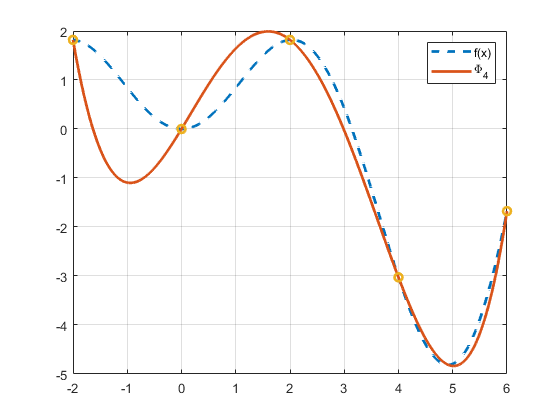

plot(x,f(x), '--', 'LineWidth', 2);
hold on;
plot(x, Phi4_plot, '-', 'LineWidth', 2);
plot(x4, f(x4), 'o','LineWidth', 2)
grid on;
legend('f(x)', '\Phi_4');
hold off;


$$n=6$$


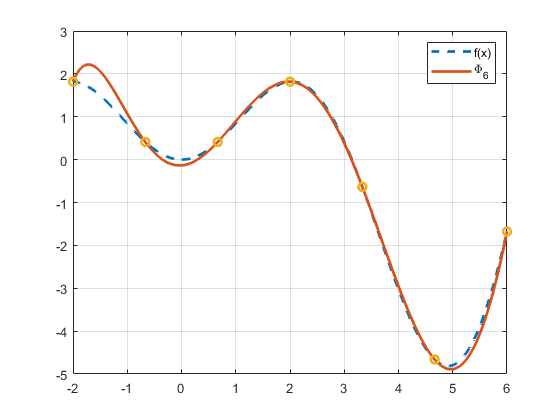

plot(x,f(x), '--','LineWidth', 2);
hold on;
plot(x, Phi6_plot, '-', 'LineWidth', 2);
plot(x6, f(x6), 'o', 'LineWidth', 2)
grid on;
legend('f(x)', '\Phi_6');
hold off;


$$n=8$$


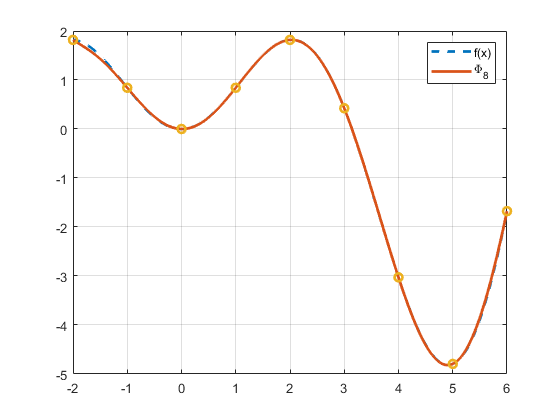

plot(x,f(x), '--', 'LineWidth', 2);
hold on;
plot(x, Phi8_plot, '-', 'LineWidth', 2);
plot(x8, f(x8), 'o','LineWidth', 2)
grid on;
legend('f(x)', '\Phi_8');
hold off;

### b. Interpolation error

#### 1. Estimate the interpolation error when resorting to a quadratic interpolation using the theorical result

From theorical result we know that:

- For $n=4$, the derivative upper bound is 11

- For $n=6$, the derivative upper bound is 13

- For $n=8$, the derivative upper bound is 15

deriv_upper_bound = {};
deriv_upper_bound{4} = 11;
deriv_upper_bound{6} = 13;
deriv_upper_bound{8} = 15;

err_est = @(n) (xn{n}(2)-xn{n}(1))^(n+1)/(4*(n+1)) * deriv_upper_bound{n};

err_est_4 = err_est(4)

err_est_4 = 17.6000

err_est_6 = err_est(6)

err_est_6 = 3.4782

err_est_8 = err_est(8)

err_est_8 = 0.4167

Let's plot the error:


$$n=4$$


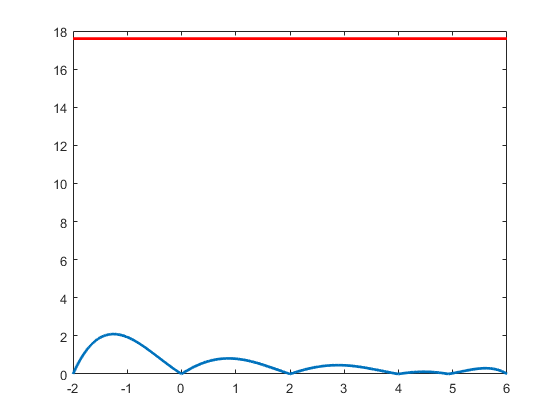

err_4 = abs(f(x) - Phi4_plot);
plot(x,err_4, '-', 'LineWidth', 2);
hold on;
plot(x, err_est_4*ones(size(x)), '-r','LineWidth',2,'MarkerSize',12);
hold off;


$$n=6$$


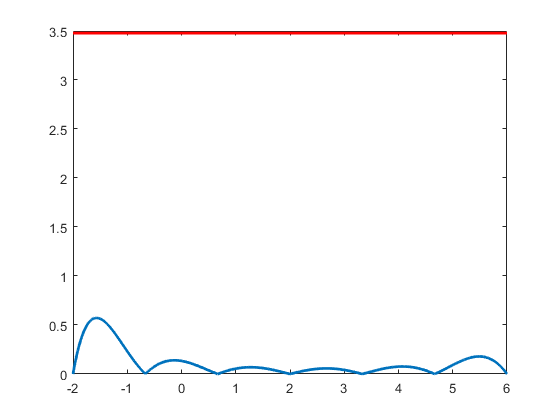

err_6 = abs(f(x) - Phi6_plot);
plot(x,err_6, '-', 'LineWidth', 2);
hold on;
plot(x, err_est_6*ones(size(x)), '-r','LineWidth',2,'MarkerSize',12);
hold off;


$$n=8$$


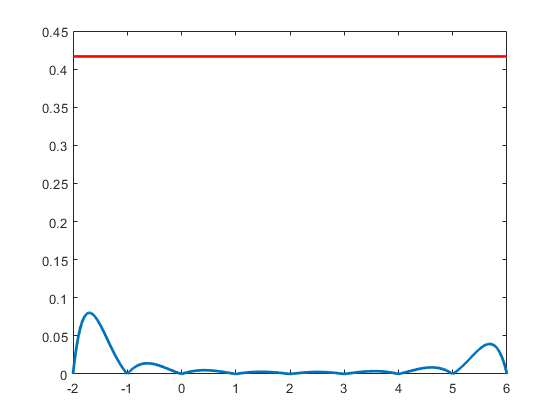

err_8 = abs(f(x) - Phi8_plot);
plot(x,err_8, '-', 'LineWidth', 2);
hold on;
plot(x, err_est_8*ones(size(x)), '-r','LineWidth',2,'MarkerSize',12);
hold off;

#### c1. Piecewise linear interpolation


$$n=5$$


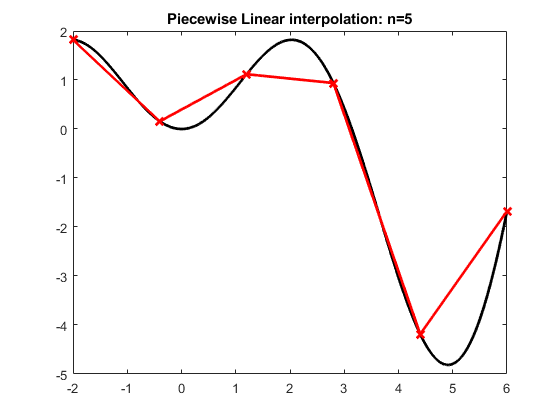

n = 5;
xint = linspace(a, b, n+1);
yint = f(xint);

y_plot = interp1(xint, yint, x);

plot(x, f(x), 'k-', x, y_plot, 'r-', xint, yint, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title('Piecewise Linear interpolation: n=5') ;
hold off;


$$n=10$$


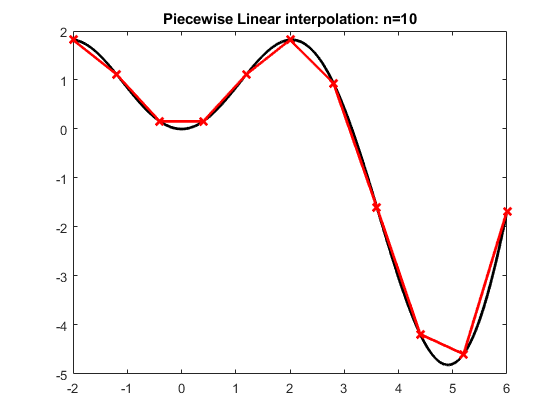

n = 10;
xint = linspace(a, b, n+1);
yint = f(xint);

y_plot = interp1(xint, yint, x);

plot(x, f(x), 'k-', x, y_plot, 'r-', xint, yint, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title('Piecewise Linear interpolation: n=10') ;
hold off;


$$n=20$$


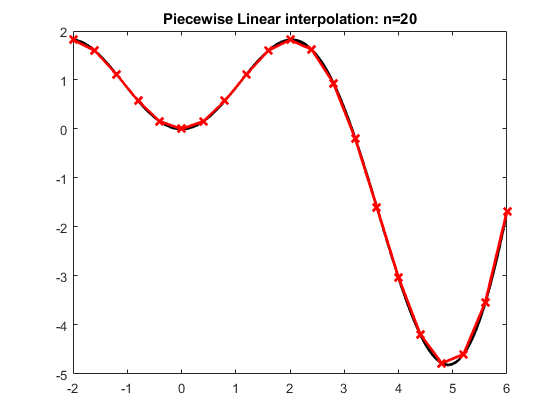

n = 20;
xint = linspace(a, b, n+1);
yint = f(xint);

y_plot = interp1(xint, yint, x);

plot(x, f(x), 'k-', x, y_plot, 'r-', xint, yint, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title('Piecewise Linear interpolation: n=20') ;
hold off;

#### c2. Cubic spline interpolation


$$n=5$$


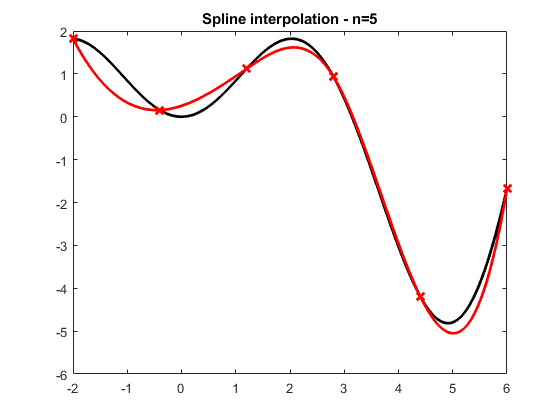

n=5;
xsp = linspace(a, b, n+1);
ysp = f(xsp);
y_plot = spline(xsp, ysp, x);

figure;
plot(x, f(x), 'k-', x, y_plot, 'r-', xsp, ysp, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title ('Spline interpolation - n=5')


$$n=10$$


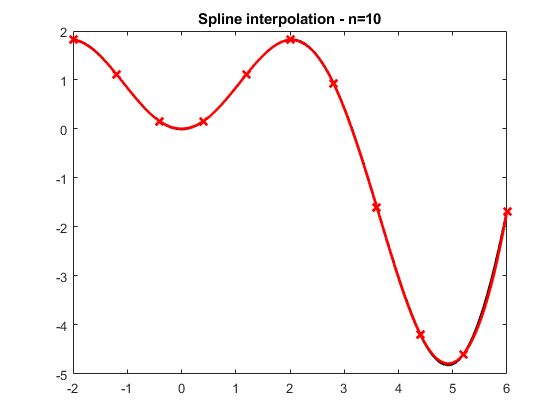

n=10;
xsp = linspace(a, b, n+1);
ysp = f(xsp);
y_plot = spline(xsp, ysp, x);

figure;
plot(x, f(x), 'k-', x, y_plot, 'r-', xsp, ysp, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title ('Spline interpolation - n=10')


$$n=20$$


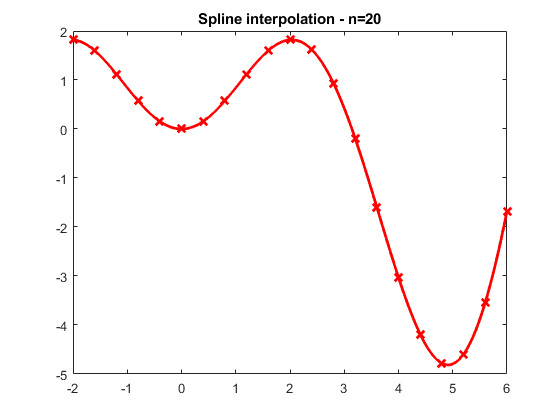

n=20;
xsp = linspace(a, b, n+1);
ysp = f(xsp);
y_plot = spline(xsp, ysp, x);

figure;
plot(x, f(x), 'k-', x, y_plot, 'r-', xsp, ysp, 'rx', 'LineWidth', 2, 'MarkerSize', 8)
title ('Spline interpolation - n=20')